ECE 537 - Assignment 1

% Question 5 
muA = [0 4 7]; 
muB = [10 5 5];
muC = [-2 -5 -5]; 

sigmaA = [6.5000 2.1651 1.2500; 2.1651 5.1250 2.3816; 1.2500 2.3816 2.3750];
sigmaB = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456; -1.4481 -0.6456 1.2880]; 
sigmaC = [6.8928 -1.3750 3.1945; -1.3750 3.3572 0.6945; 3.1945 0.6945 3.7500];

dataA = gaussian(muA, sigmaA, 1000, length(muA));
% sample_muA = mean(dataA)
% sample_sigmaA = cov(dataA)

dataB = gaussian(muB, sigmaB, 1000, length(muB));
% sample_muB = mean(dataB)
% sample_sigmaB = cov(dataB)

dataC = gaussian(muC, sigmaC, 1000, length(muC));
% sample_muC = mean(dataC)
% sample_sigmaC = cov(dataC)


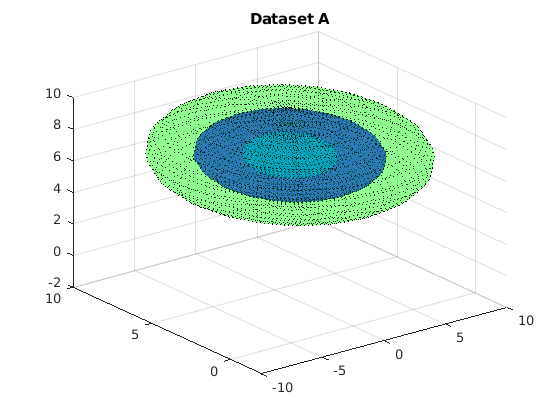

% Question 6 

[Ap_axes, Ax_c1, Ay_c1, Az_c1, Ax_c2, Ay_c2, Az_c2, Ax_c3, Ay_c3, Az_c3] = spheres(dataA);
Ac1 = surf(Ax_c1, Ay_c1, Az_c1,'FaceAlpha',0.75, 'LineStyle', ':', 'FaceColor', 'c');
hold on 
Ac2 = surf(Ax_c2, Ay_c2, Az_c2,'FaceAlpha',0.45, 'LineStyle', ':', 'FaceColor', 'b');
Ac3 = surf(Ax_c3, Ay_c3, Az_c3,'FaceAlpha',0.25, 'LineStyle', ':', 'FaceColor', 'g');
Ap1 = line(Ap_axes(1,1), Ap_axes(2,1), Ap_axes(3,1), 'Color','k');
Ap2 = line(Ap_axes(1,2), Ap_axes(2,2), Ap_axes(3,2));
Ap3 = line(Ap_axes(1,3), Ap_axes(2,3), Ap_axes(3,3));
title ('Dataset A');
hold off 

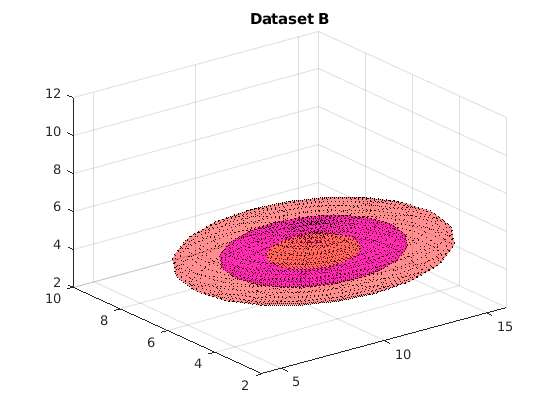


[Bp_axes, Bx_c1, By_c1, Bz_c1, Bx_c2, By_c2, Bz_c2, Bx_c3, By_c3, Bz_c3] = spheres(dataB);
Bc1 = surf(Bx_c1, By_c1, Bz_c1, 'LineStyle', ':', 'FaceColor', 'y');
hold on 
Bc2 = surf(Bx_c2, By_c2, Bz_c2,'FaceAlpha',0.45, 'LineStyle', ':', 'FaceColor', 'm');
Bc3 = surf(Bx_c3, By_c3, Bz_c3,'FaceAlpha',0.25, 'LineStyle', ':', 'FaceColor', 'r');
Bp1 = line (Bp_axes(1,1), Bp_axes(2,1), Bp_axes(3,1));
Bp2 = line (Bp_axes(1,2), Bp_axes(2,2), Bp_axes(3,2));
Bp3 = line (Bp_axes(1,3), Bp_axes(2,3), Bp_axes(3,3));
title ('Dataset B');
hold off 

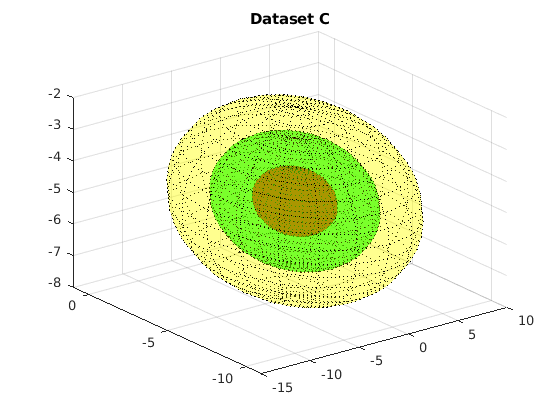


[Cp_axes, Cx_c1, Cy_c1, Cz_c1, Cx_c2, Cy_c2, Cz_c2, Cx_c3, Cy_c3, Cz_c3] = spheres(dataC);
Cc1 = surf(Cx_c1, Cy_c1, Cz_c1, 'LineStyle', ':', 'FaceColor', 'r');
hold on 
Cc2 = surf(Cx_c2, Cy_c2, Cz_c2,'FaceAlpha',0.45, 'LineStyle', ':', 'FaceColor', 'g');
Cc3 = surf(Cx_c3, Cy_c3, Cz_c3,'FaceAlpha',0.25, 'LineStyle', ':', 'FaceColor', 'y');
Cp1 = line (Cp_axes(1,1), Cp_axes(2,1), Cp_axes(3,1));
Cp2 = line (Cp_axes(1,2), Cp_axes(2,2), Cp_axes(3,2));
Cp3 = line (Cp_axes(1,3), Cp_axes(2,3), Cp_axes(3,3));
title ('Dataset C');

function[p_axes, x_c1, y_c1, z_c1, x_c2, y_c2, z_c2,x_c3, y_c3, z_c3]=spheres(data)
    mu = mean(data);
    sigma = cov(data);
    [Vs, Ds] = eigs(sigma);
    
    p_axes_len = sqrt(diag(Ds));
    p_axes = Vs*sqrt(Ds)+mu;
    
    [x_c1, y_c1, z_c1] = ellipsoid(mu(1), mu(2), mu(3),p_axes_len(1), p_axes_len(2), p_axes_len(3), 20);
    [x_c2, y_c2, z_c2] = ellipsoid(mu(1), mu(2), mu(3),2*p_axes_len(1), 2*p_axes_len(2), 2*p_axes_len(3), 20);
    [x_c3, y_c3, z_c3] = ellipsoid(mu(1), mu(2), mu(3),3*p_axes_len(1), 3*p_axes_len(2), 3*p_axes_len(3), 20);
    
end



function[data]=gaussian(mu, sigma, k, d)
    
    sample_data = randn(k,d);
    data = sample_data - mean(sample_data); % zero mean data
    
    [V,D]= eigs(cov(data));
    Aw = V*sqrt(inv(D)); % whitening transform
    data = data*Aw; % identity covarriance, zero mean data 
    
    [V_d, D_d] = eigs(sigma); % desired eigenvalues and eigenvectors
    Ac = sqrt(D_d)*inv(V_d);
    data = data*Ac; % data with desired covariance
    
    data = data+mu; % data with desired covarriance and desired mean

end